clear
clc
windowSize = 4096;
hopSize = 2048;
BPM = 110;
beats = 1/(BPM/60)

beats = 0.5455

quantification = beats/8 %double croche

quantification = 0.0682

wavFile = 'AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav'

wavFile = 'AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav'

[x,fs] = audioread(wavFile);
window = hann(windowSize,"symmetric")

window =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


x = x(:,1)

x =     0.0001
    0.0003
    0.0005
    0.0007
    0.0009
    0.0012
    0.0015
    0.0019
    0.0023
    0.0029


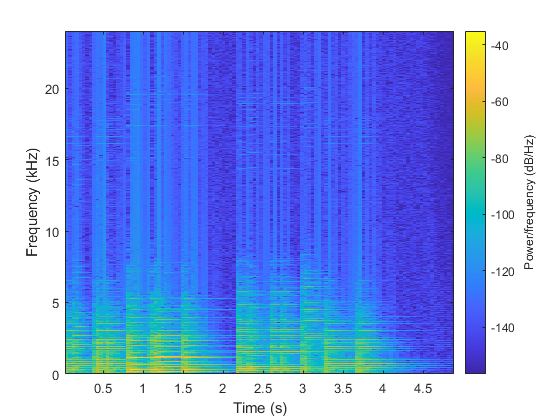


spectrogram(x,windowSize,windowSize-hopSize,windowSize,fs,'yaxis');



%first methode
audio = miraudio(wavFile,'Normal');

Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing mirsum related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Elapsed time is 0.211674 seconds.


Computing mirfilterbank related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
 
filterBank is the Audio waveform related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav, of sampling rate 48000 Hz.


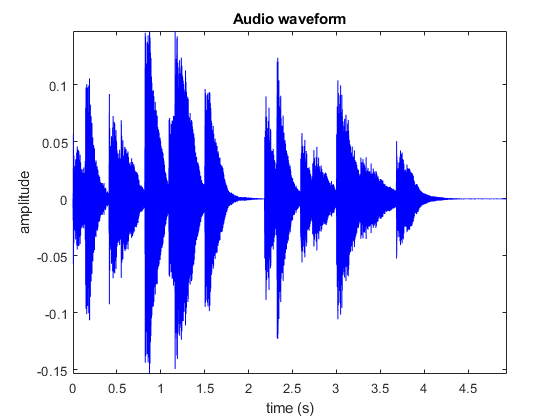

Its content is displayed in Figure 2.
 



filterBank = mirfilterbank(audio,'Gammatone','Channel',7)

Computing mirenvelope related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
 
enveloppe is the Differentiated envelope (half-wave rectified) related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav, of sampling rate 3000 Hz.


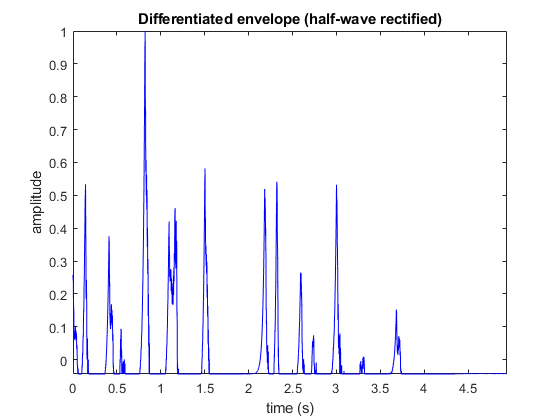

Its content is displayed in Figure 3.
 


%methode de suiveur envelope avec peak picking
enveloppe = mirenvelope(filterBank, 'FilterType', 'IIR','HalfwaveCenter','Diff','Normal','Center')

Computing mirpeaks related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
 
envelopepeaks is the Differentiated envelope (half-wave rectified) related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav, of sampling rate 3000 Hz.


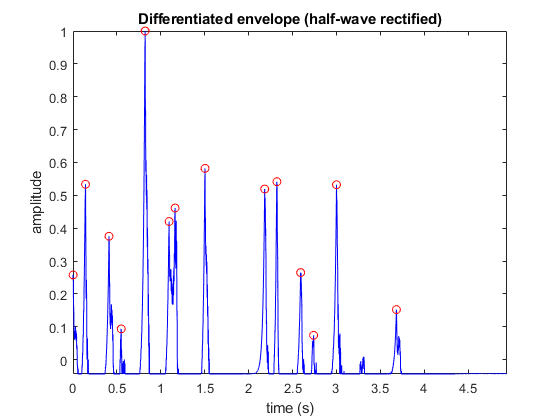

Its content is displayed in Figure 4.
 



envelopepeaks = mirpeaks(enveloppe,'Threshold',0.02,'Reso',quantification)

envelopedata =  mirgetdata(envelopepeaks)

envelopedata =     0.8217
    1.5035
    2.3221
    0.1423
    3.0011
    2.1829
    1.1626
    1.0944
    0.4100
    2.5922


envelopedataSort = sort(envelopedata(:,:,1))

envelopedataSort =     0.0009
    0.1423
    0.4100
    0.5489
    0.8217
    1.0944
    1.1626
    1.5035
    2.1829
    2.3221




nbrNotes = length(envelopedataSort)

nbrNotes = 14

 
sg is the Audio waveform related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav, of sampling rate 48000 Hz.


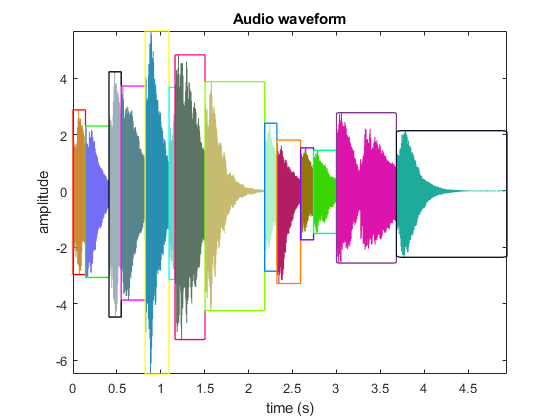

Its content is displayed in Figure 5.
 


sg = mirsegment(audio,envelopepeaks)

segmentPosition = get(sg,'FramePos')

segmentPosition = 1×1 cell array
    {1×15 cell}


posOfLastSg = segmentPosition{1}(size(segmentPosition{1},2))

posOfLastSg = 1×1 cell array
    {2×1 double}



%store the segmented data
for i =1:nbrNotes
    
    
    if i == nbrNotes
        segmentedNotes{i} = miraudio(audio,'Extract' , posOfLastSg{1}(1),posOfLastSg{1}(2));
        duration(i) = 0.25;
    else
        segmentedNotes{i} = miraudio(audio,'Extract' ,envelopedataSort(i),envelopedataSort(i+1));
        duration(i) = envelopedataSort(i+1)-envelopedataSort(i);
    end
    theAudio = mirgetdata(segmentedNotes{i});
    theAudio = theAudio.';
    [time, f0] = yin_estimator(theAudio,48000);
    
    stdF0 = median(f0);
    
    midifreq (i,1) = round( hz2midi(stdF0));
end

Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...
Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110

Computing miraudio related to AudioTest\JAFUNK_midi_bass_loop_flapper_01_110.wav...




matrix(:,1) = envelopedataSort(:)/beats;
matrix(:,2) = duration/beats;
matrix(:,3) = 1.0;
matrix(:,4) = midifreq;
matrix(:,5) = 100;
matrix(:,6) = envelopedataSort(:);
matrix(:,7) = duration(:)

matrix =     0.0017    0.2592    1.0000   50.0000  100.0000    0.0009    0.1414
    0.2609    0.4908    1.0000   50.0000  100.0000    0.1423    0.2677
    0.7517    0.2545    1.0000   50.0000  100.0000    0.4100    0.1388
    1.0063    0.5001    1.0000   50.0000  100.0000    0.5489    0.2728
    1.5064    0.5001    1.0000   52.0000  100.0000    0.8217    0.2728
    2.0064    0.1250    1.0000   52.0000  100.0000    1.0944    0.0682
    2.1315    0.6250    1.0000   53.0000  100.0000    1.1626    0.3409
    2.7565    1.2456    1.0000   52.0000  100.0000    1.5035    0.6794
    4.0021    0.2551    1.0000   48.0000  100.0000    2.1829    0.1392
    4.2572    0.4951    1.0000   48.0000  100.0000    2.3221    0.2701




writemidi(matrix,'miditest.mid',BPM);